# Read Horizon files

Cory Puckett

This file will take the output of Horizons and reads each file to a table that can be read later in the program.

When generating the files in horizons use the Moon (body center) as the cordinate center and use the below table settings. In order for everthing to work correctly you need to choose a start date in AD in Horizons.

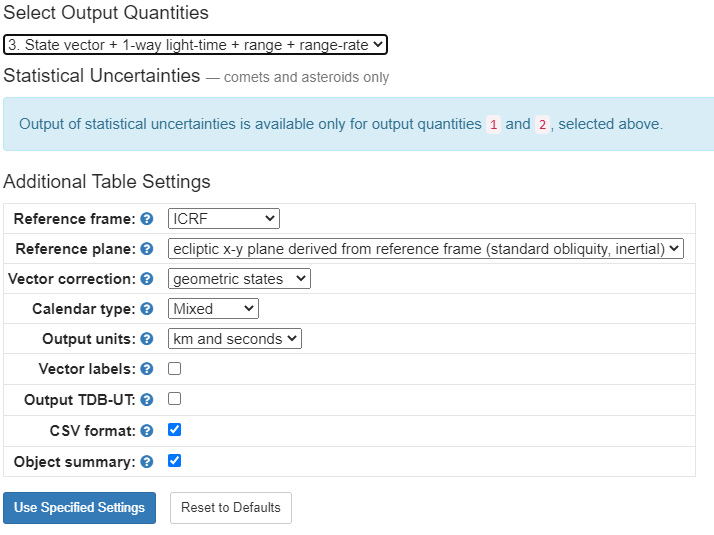

[Earth.txt](matlab:open('Earth.txt')) contains the position vector data of earth relative to the moon from Jan-1-2000 to Dec-31-2030.

[Sun.txt](matlab:open('Sun.txt')) contains the position vector data of the Sun relative to the moon from Jan-1-2000 to Dec-31-2030.

[EMBC.txt](matlab:open('EMBC.txt')) contains the position vector data of the Earth-Moon Bary center (EMBC) relative to the moon from Jan-1-2000 to Dec-31-2030.

clear opts;
opts = delimitedTextImportOptions('NumVariables',11); 
%This sets up how many columns there are
opts.Delimiter = [",",", A.D."];
%This sets up the delimiters. The AD is there to remove it because I
%couldn't find a format to read it
opts.VariableNames = ["JDTDB", "Date", "X", "Y", "Z", "VX", "VY", "VZ", "LT", "RG", "RR"];
%Colmun names
opts = setvartype(opts,{'double'});
%Sets all data types to doubles
opts = setvartype(opts,"Date",{'datetime'});
%Changes Date to datetime type
opts = setvaropts(opts,"Date","InputFormat","yyy-MMM-dd HH:mm:SS.ssss");
%Sets up input format for date and time of each position vector

%Declaring variables as global, so that they can be used in functions
global earth sun EMBC
%This then reads each of the files and saves it by the name and at the
%needed start point
for i = 3 %Change this to 1:3 if you want to read all three files.
    if i == 1
        opts.DataLines = 55;
        earth = readtable("Earth.txt",opts);
        earth = earth(isfinite(earth.JDTDB),1:11);
        %This line trims the lines talking about cordinates at the end of each file.
    elseif i == 2
        opts.DataLines = 35;
        EMBC = readtable("EMBC.txt",opts);
        EMBC = EMBC(isfinite(EMBC.JDTDB),1:11);
        %EMBC is Earth Moon Bary Center
    else
        opts.DataLines = 55;
        sun = readtable("Sun.txt",opts);
        sun = sun(isfinite(sun.JDTDB),1:11);
    end
end